# Create and Customize semilogy Plots 

Semilog plot (y-axis has log scale)

### Create Data

Use a helper function to generate vectors of points of exponential functions.

[x,y1,y2] = createData();

### Basic semilogy Plot

Plot the function $y=x^2$ with a logarithmic y-axis using `semilogy`.

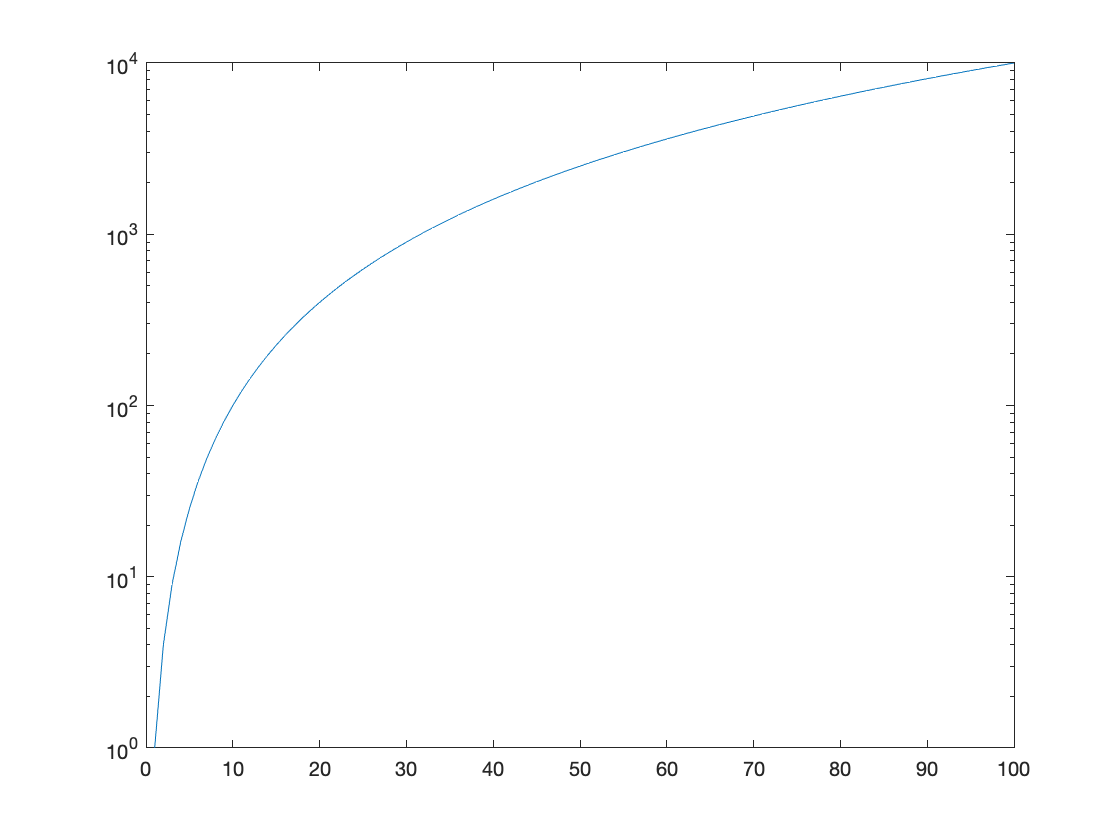

semilogy(x,y1)

## Customization

### Customize Line Appearance

Specify the line type and color for the second line plot by using a vector of line specification characters in the *LineSpec *input argument into `semilogy`. The *LineWidth* property can be specified using a Name, Value pair to improve line visibility. 

LineType = '--'

LineType = '--'

LineColor = 'r'

LineColor = 'r'

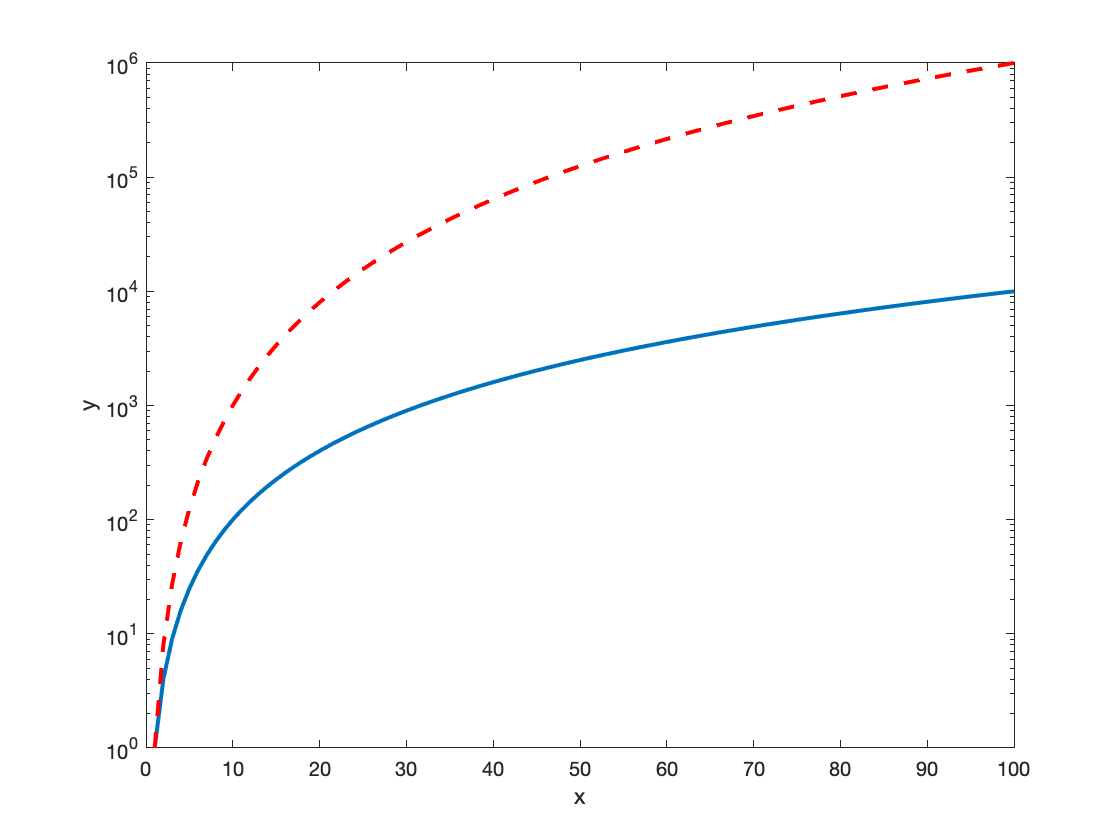

LineWidth = 2;

s = semilogy(x,y1,x,y2,...
    [LineType LineColor],...    % Specify line type and color for the second plot
    "LineWidth",LineWidth);     % Specify line width
xlabel("x")
ylabel("y")

### Add a Legend and a Grid

Use the grid with `semilogy` to clearly display the logarithmic axis and add a legend to label the plot lines.

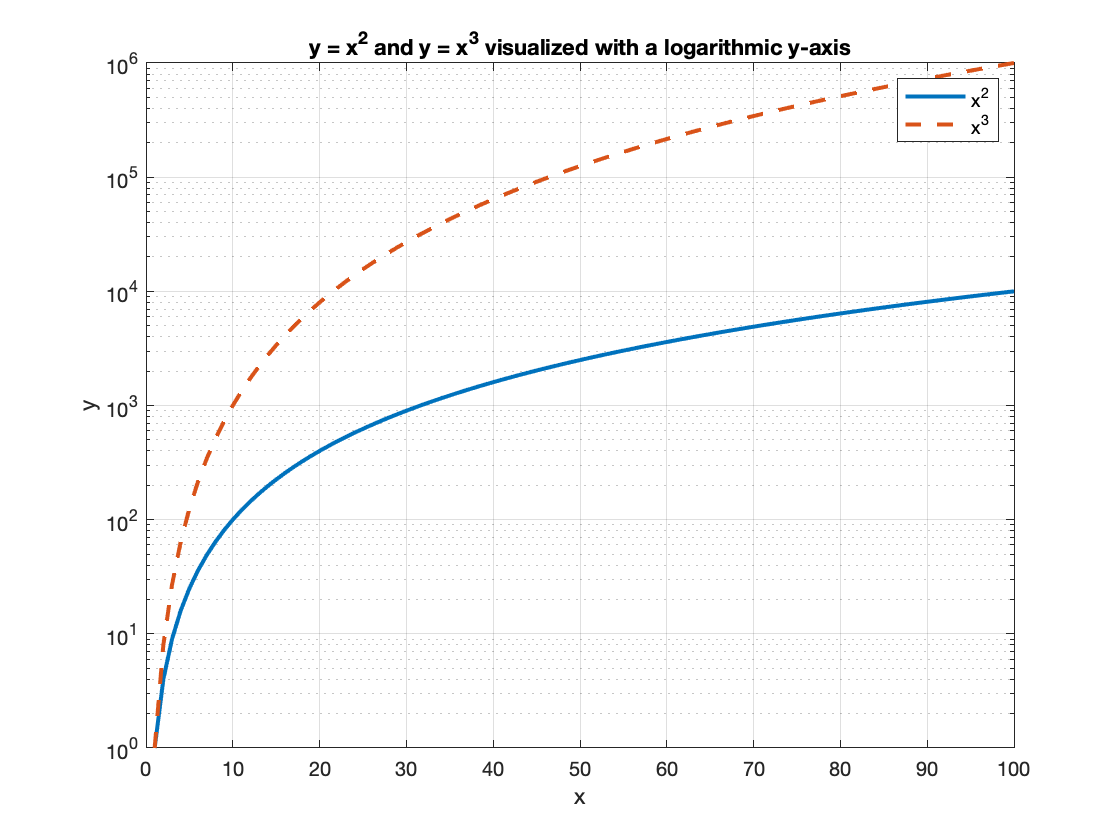

figure
s1 = semilogy(x,y1,x,y2,...
    '--',...                    % Specify a dashed line for the second line     
    "LineWidth",2);             % Specify line width for both lines

legend("x^{2}","x^{3}")
grid on
xlabel("x")
ylabel("y")
title("y = x^{2} and y = x^{3} visualized with a logarithmic y-axis")

## **Additional Information**

### **Get All Line Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Line, uncomment the following code. View or modify these properties using dot notation.

% get(s(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[semilogy](https://www.mathworks.com/help/matlab/ref/semilogy.html)

### Helper Functions

This function generates x and y data.

function [x,y1,y2] = createData()
    x = 1:100;
    y1 = x.^2;
    y2 = x.^3;
end

Copyright (c) 2021, The MathWorks, Inc.